Define function to integrate

f=@(x) 1./x;
xi=linspace(2,10,51);
fi=f(xi);
Integral=MySimpson(fi,xi);
fprintf('Exact value of integral is %f\n',log(10)-log(2))

Exact value of integral is 1.609438


fprintf('Simpson rule give %f\n', Integral)

Simpson rule give 1.609439


fprintf('Trapezoidal rule give %f\n', trapz(xi,fi))

Trapezoidal rule give 1.609950


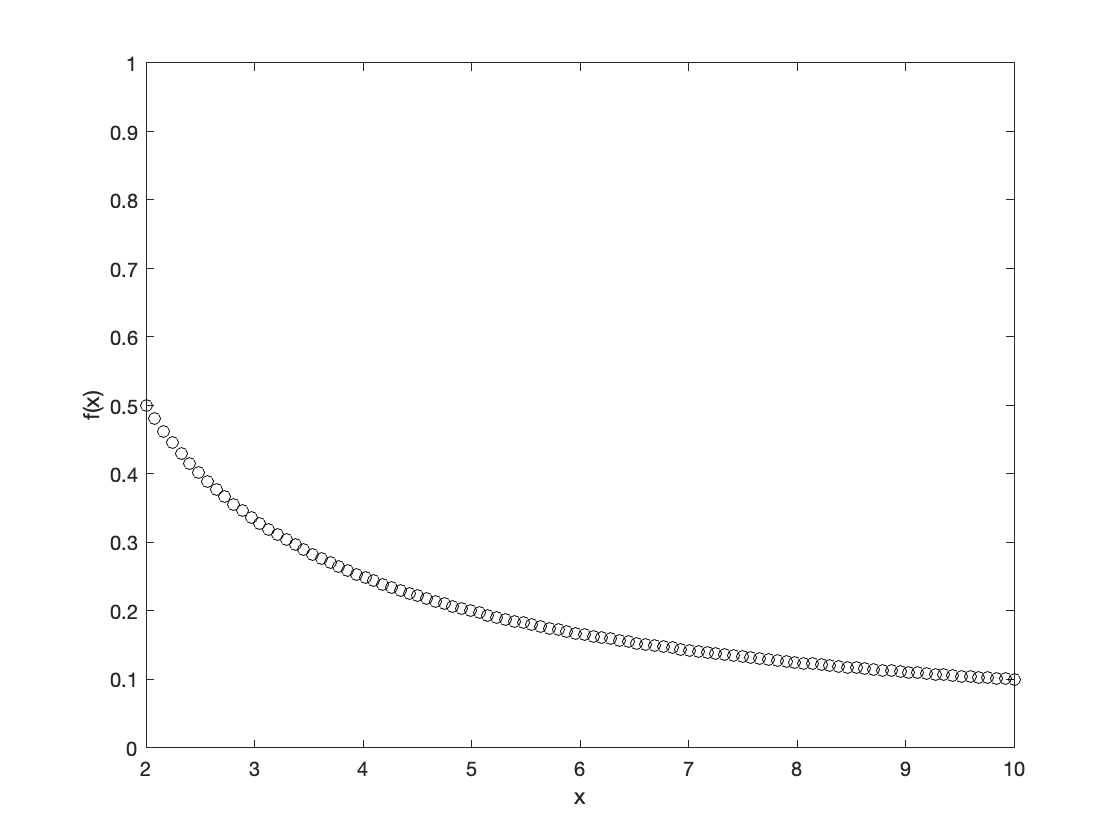

x=linspace(2,10);
plot(x,f(x),'ko')
axis([2 10 0 1])
xlabel('x')
ylabel('f(x)')

function Int=MySimpson(fi,xi)
if(rem(length(fi),2)==0)
    fprintf('Simpson rule will only work with odd number of elements');
    Int=0;
else
    Delta=xi(2)-xi(1);
    Int=fi(1);
    Int=Int+4*sum(fi(2:2:end-1));
    Int=Int+2*sum(fi(3:2:end-2)); %end-1 will work as well!
    Int=Int+fi(end);
    Int=(Delta/3.0)*Int;
end
end